# Goal of the assignment: to do data pre-processing

in order to be able to feed the pre-processed data onto a NLP neural network

clc; clear all; close all; 

## Import data

filename = "pg74709.txt";
textData = extractFileText(filename);



## Tokenize data

documents = tokenizedDocument(textData);
rawBag    = bagOfWords(documents)

rawBag =   bagOfWords with properties:

          Counts: [1×7556 double]
      Vocabulary: [""    "The"    "Project"    "Gutenberg"    "eBook"    "of"    "A"    "knight"    "the"    "air"    "This"    "ebook"    "is"    "for"    "use"    "anyone"    "anywhere"    "in"    "United"    "States"    "and"    "most"    …    ]
        NumWords: 7556
    NumDocuments: 1


## Remove stop words

Note: modern NLP models do not need this step

documents = addPartOfSpeechDetails(documents); % This helps the removal of stop words.
documents = removeStopWords(documents);
documents = normalizeWords(documents,'Style','lemma');
documents = erasePunctuation(documents);
documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);
afterBag  = bagOfWords(documents);


## Statistics on the preprocessing

Bags of words and n-grams

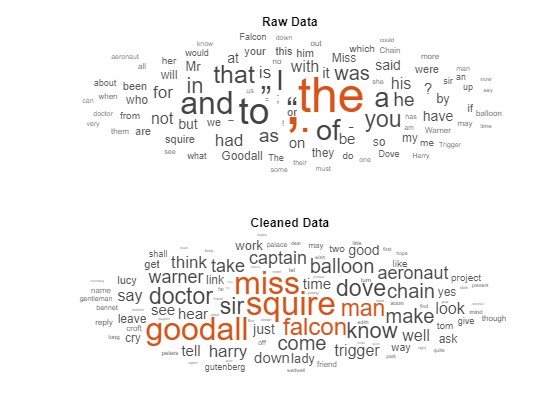

figure;
nexttile;
wordcloud(rawBag);
title("Raw Data")

nexttile;
wordcloud(afterBag);
title("Cleaned Data")

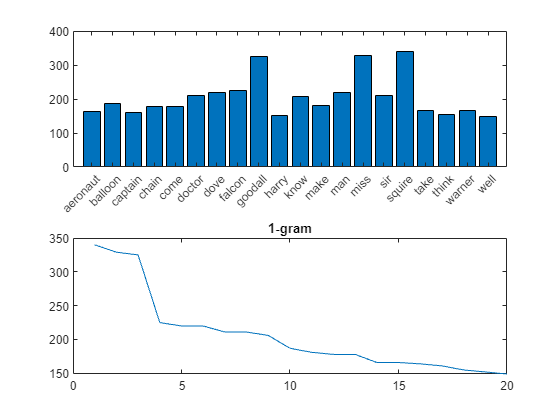

tblWords = topkwords(afterBag, 20);

figure; 
nexttile;
bar(categorical(tblWords.Word), tblWords.Count);

nexttile;
plot(tblWords.Count);
title("1-gram");

## N-gram analysis

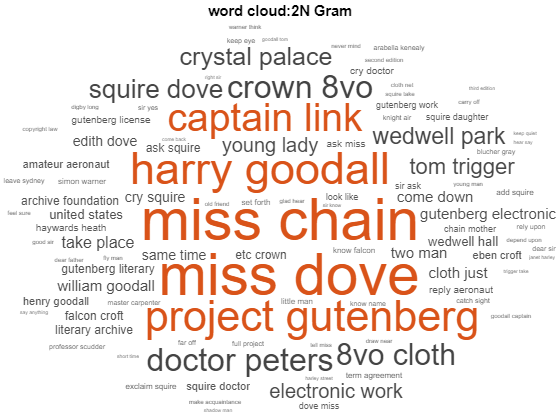

% 2N gram
bag2n = bagOfNgrams(documents, NGramLengths=2);
figure
wordcloud(bag2n);
title("word cloud:2N Gram")

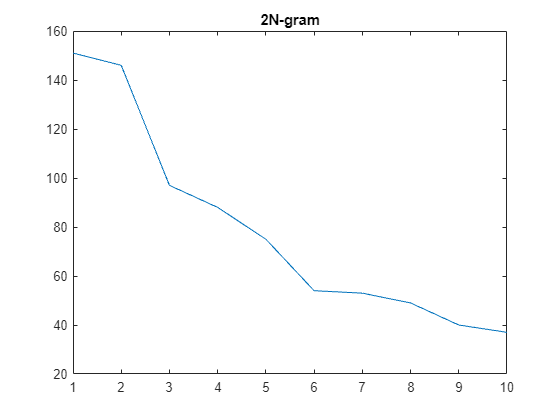


tblWords = topkngrams(bag2n, 10);

figure; 
plot(tblWords.Count);
title("2N-gram");

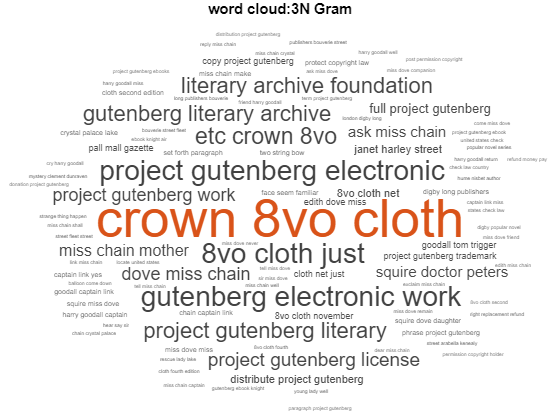




% 3N Gram
bag3n = bagOfNgrams(documents, NGramLengths=3);
figure
wordcloud(bag3n);
title("word cloud:3N Gram")

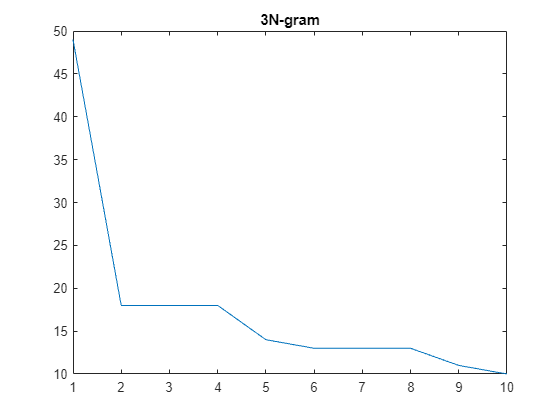

% 3N gram graph
tblWords = topkngrams(bag3n, 10);

figure; 
plot(tblWords.Count);
title("3N-gram");

## Converting documents into sequences

textData = replace(textData,"  ","");
textData = split(textData,[newline newline]); % Split the text into separate paragraphs
textData = textData(5:2:end);

textData


textData = 

  1×0 empty string array



## Sequences of vectors for the predictors and categorical sequences for responses

Create special characters to denote "start of text", "whitespace", "end of text" and "newline". Use the special characters `"\x0002"` (start of text), `"\x00B7"` ("·", middle dot), `"\x2403"` ("␃", end of text), and `"\x00B6"` ("`¶`", pilcrow) respectively. To prevent ambiguity, you must choose special characters that do not appear in the text. Because these characters do not appear in the training data, they can be used for this purpose.

startOfTextCharacter    = compose("\x0002");
whitespaceCharacter     = compose("\x00B7");
endOfTextCharacter      = compose("\x2403");
newlineCharacter        = compose("\x00B6");


## Processing the data

so we can use them as inputs in a NN. 


textData            = startOfTextCharacter + textData;
textData            = replace(textData,[" " newline],[whitespaceCharacter newlineCharacter]);
uniqueCharacters    = unique([textData{:}]);
numUniqueCharacters = numel(uniqueCharacters);
numDocuments        = numel(textData);
XTrain              = cell(1,numDocuments);
YTrain              = cell(1,numDocuments);

for i = 1:numel(textData)
    characters      = textData{i};
    sequenceLength  = numel(characters);
    
    % indices of characters
    [~,idx] = ismember(characters,uniqueCharacters);
    
    % characters to vectors
    X = zeros(numUniqueCharacters,sequenceLength);
    for j = 1:sequenceLength
        X(idx(j),j) = 1;
    end
    
    % vector of categorical responses with end of text character
  
 
    charactersShifted = [cellstr(characters(2:end)')' endOfTextCharacter];
    
    Y = categorical(charactersShifted);
    
    XTrain{i} = X;
    YTrain{i} = Y;


textData{1}
YTrain{1}
end